# 微分方程(组)求解

## 求解析解

% 若不指定自变量，则默认为 t
dsolve('y-Dy=2*exp(x)','y(0)=1','x'); % Matlab官方已不推荐使用

syms y(x) a % 该形式定义会指定自变量为x
eqn = (y-diff(y,x,1) == 2*a*x);
dsolve(eqn,y(0)==1)

$$ans = 2\,a+2\,a\,x-{\mathrm{e}}^{x}\,\left(2\,a-1\right)$$

## 方程组

syms y(t) x(t) z(t)
eqn = [diff(x,t)==2*x-3*y+3*z+t, diff(y,t)==4*x-5*y+3*z+t, diff(z,t)==4*x-4*y+2*z+t];
eqn

$$eqn(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}x\left(t\right)=t+2\,x\left(t\right)-3\,y\left(t\right)+3\,z\left(t\right) & \frac{\partial }{\partial t}y\left(t\right)=t+4\,x\left(t\right)-5\,y\left(t\right)+3\,z\left(t\right) & \frac{\partial }{\partial t}z\left(t\right)=t+4\,x\left(t\right)-4\,y\left(t\right)+2\,z\left(t\right) \end{array}\right)$$

Dy = diff(y,t); % 由于不支持连续括号语法，需先定义Dy
cond = [y(0)==0, Dy(1)==15];
solution = dsolve(eqn,cond)

solution = 包含以下字段的 struct :
    y: [1×1 sym]
    x: [1×1 sym]
    z: [1×1 sym]


solution.x = simplify(solution.x); % 可以尝试先化简
latex_reslut = latex(solution.x); % 转化为Latex格式代码输出
solution.x, solution.y, solution.z

$$ans = z\,{\mathrm{e}}^{2\,t}-\frac{t}{2}+\frac{{\mathrm{e}}^{-t}\,\left(4\,z-31\,{\mathrm{e}}^{2}+4\,z\,{\mathrm{e}}^{4}-1\right)}{2\,\left(\mathrm{e}-2\right)}-\frac{1}{4}$$

$$ans = {\mathrm{e}}^{2\,t}\,\left(z-\frac{{\mathrm{e}}^{-2\,t}\,\left(2\,t+1\right)}{4}\right)+\frac{{\mathrm{e}}^{-t}\,\left(4\,z-31\,{\mathrm{e}}^{2}+4\,z\,{\mathrm{e}}^{4}-1\right)}{2\,\left(\mathrm{e}-2\right)}-\frac{{\mathrm{e}}^{-2\,t}\,\mathrm{e}\,\left(4\,z-62\,\mathrm{e}+8\,z\,{\mathrm{e}}^{3}-1\right)}{4\,\left(\mathrm{e}-2\right)}$$

$$ans = {\mathrm{e}}^{2\,t}\,\left(z-\frac{{\mathrm{e}}^{-2\,t}\,\left(2\,t+1\right)}{4}\right)-\frac{{\mathrm{e}}^{-2\,t}\,\mathrm{e}\,\left(4\,z-62\,\mathrm{e}+8\,z\,{\mathrm{e}}^{3}-1\right)}{4\,\left(\mathrm{e}-2\right)}$$

## 求数值解

## 求解析解失败的例子

v = 1;
syms P(t) Q(t) x(t) y(t)
P = 20 + sqrt(5)/2*v*t;
Q = sqrt(5)/2*v*t;
Dx = diff(x,t);
Dy = diff(y,t);
com = 3*v/sqrt((P-x)^2 + (Q-y)^2);
eqn = [Dx==com*(P-x), Dy==com*(Q-y)];
cond = [x(0)==0, y(0)==0];
solution = dsolve(eqn, cond); % 求解析解失败

## 非刚性

tspan = [0, 2]; % 自变量范围
y0 = 3; % 初始值
[x, y] = ode45(@df1, tspan, y0); % 龙格-库塔法(利用计算机仿真)
x, y

x =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


y =     3.0000
    3.1513
    3.3052
    3.4618
    3.6214
    3.7840
    3.9499
    4.1191
    4.2918
    4.4683


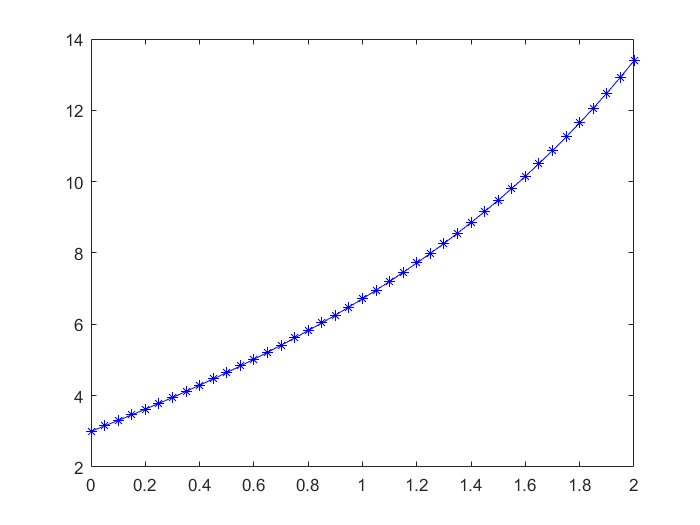

figure(1);
plot(x, y, 'b*-');

## 刚性

[x, y] = ode15s(@df1,tspan,y0);
x, y

x =          0
    0.0620
    0.1239
    0.1859
    0.3598
    0.5336
    0.7075
    0.8814
    1.0814
    1.2814


y =     3.0000
    3.1893
    3.3828
    3.5808
    4.1611
    4.7846
    5.4603
    6.1986
    7.1395
    8.1994


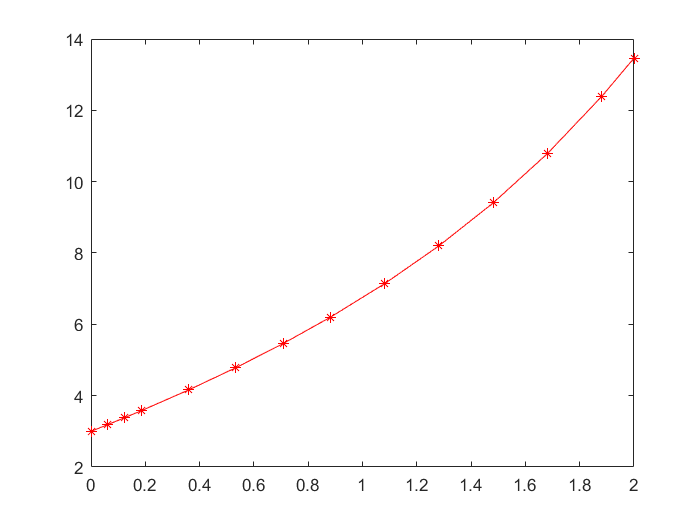

figure(2);
plot(x, y, 'r*-');

## 手动指定求解区间步长， 指定相对误差与绝对误差

tspan = 0:1e-1:2;
option = odeset("RelTol",1e-4, "AbsTol",1e-8);
[x, y] = ode15s(@df1,tspan,y0, option);
x, y

x =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


y =     3.0000
    3.3058
    3.6223
    3.9509
    4.2931
    4.6503
    5.0240
    5.4160
    5.8282
    6.2627


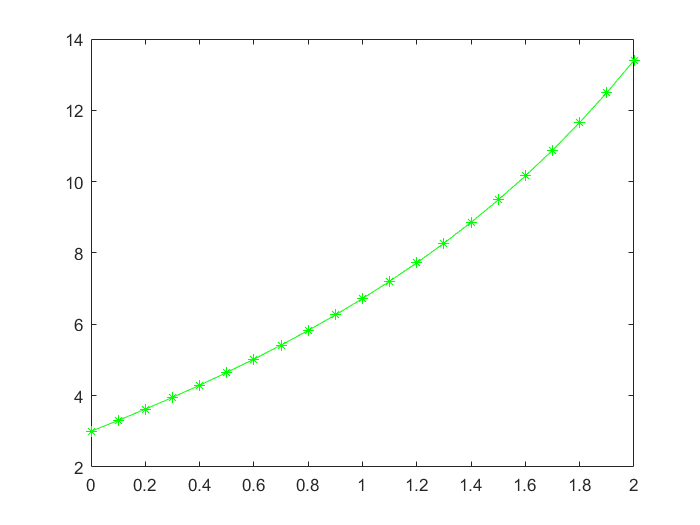

figure(3);
plot(x, y, 'g*-');

## 方程组

tspan = [0, 4*pi];
y0 = [0 1 1]; % 即 x = 0 时y的取值
[x, y] = ode45(@df2, tspan,y0);
x, y

x =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


y =          0    1.0000    1.0000
    0.0001    1.0000    1.0000
    0.0001    1.0000    1.0000
    0.0002    1.0000    1.0000
    0.0002    1.0000    1.0000
    0.0005    1.0000    1.0000
    0.0007    1.0000    1.0000
    0.0010    1.0000    1.0000
    0.0012    1.0000    1.0000
    0.0025    1.0000    1.0000


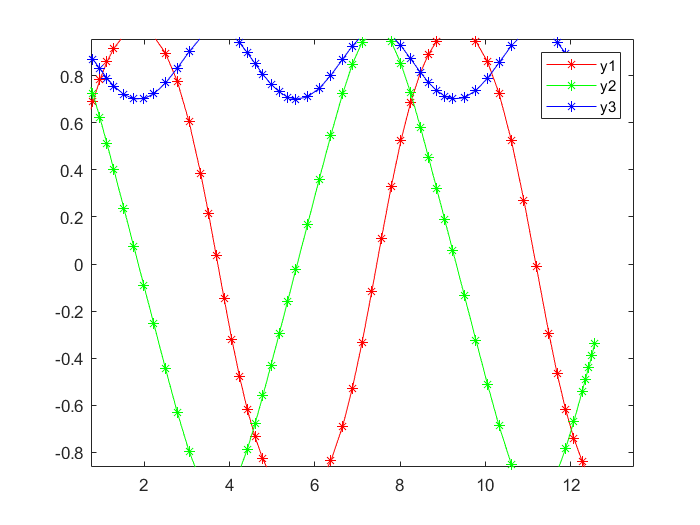

figure(4);
plot(x, y(:,1), 'r*-');
hold on;
plot(x, y(:,2), 'g*-');
hold on;
plot(x, y(:,3), 'b*-');
legend('y1','y2','y3');

## 高阶微分方程

% 将高阶导数重命名为新变量(如y1=y,y2=Dy,y3=D2y)，重命名后要将原来存在的求导关系转换为方程
% (如y2=Dy1)加入dy_n

% (每一个dy(k)都是对y(k)的一阶求导，这是严格对应的)方程组(这是重命名可行性的核心原理)
% 标准形式为 dy_n = f(...) 其中 n=1,2,...
tspan = [-2, 2];
y0 = [3 4]; % y0是基于tspan的起始值(此处为-2,即y(-2)=3,dy(-2)=4)
[x, y] = ode45(@df3, tspan, y0); % 对n阶微分方程，solver返回 0 ~ n-1阶的结果
x, y

x =    -2.0000
   -1.9623
   -1.9246
   -1.8870
   -1.8493
   -1.7493
   -1.6493
   -1.5493
   -1.4493
   -1.3493


y =     3.0000    4.0000
    3.1485    3.8806
    3.2925    3.7634
    3.4321    3.6485
    3.5674    3.5359
    3.9065    3.2480
    4.2176    2.9761
    4.5022    2.7202
    4.7621    2.4803
    4.9988    2.2565


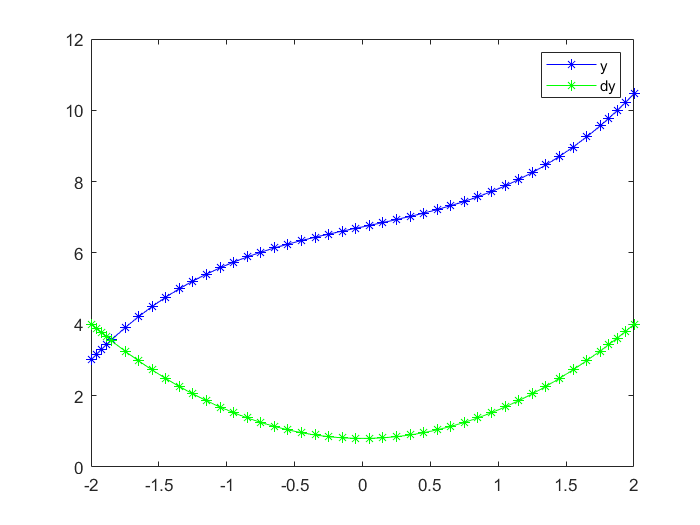

plot(x, y(:,1),'b*-', x, y(:,2),'g*-');
legend('y','dy');

函数定义

function dy = df1(x, y)
    dy = y-2*x;
end

function dy = df2(~, y)
    dy = zeros(3, 1);
    dy(1) = y(2)*y(3);
    dy(2) = -y(1)*y(3);
    dy(3) = -0.51*y(1)*y(2);
end

function dy = df3(x, y)
    dy = zeros(2, 1);
    % 对应y0=[3,4]
    dy(1) = y(2);
    dy(2) = 2*x*y(2)/(1+x^2);
    % 对应y0=[4,3] 两者结果相同(但在y中的列顺序不同)
%     dy(1) = 2*x*y(1)/(1+x^2);
%     dy(2) = y(1);
end
